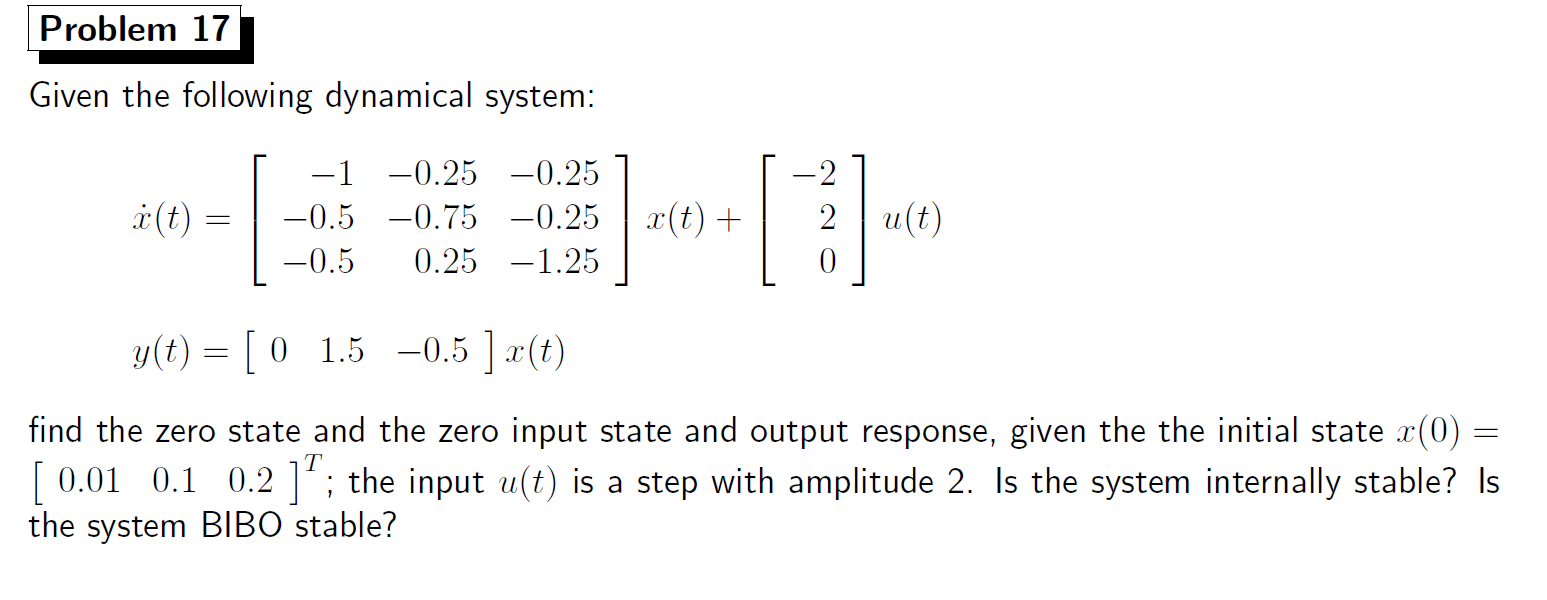

A=[
-1 -0.25 -0.25
-0.5 -0.75 -0.25
-0.5 -0.25 -1.25];

B=[-2 2 0]';
C=[0 1.5 -.5 ];
D=[0];

sys=ss(A,B,C,D);
s=tf('s');
H=tf(sys)

H =
 
        3 s^2 + 8 s + 4.75
  ------------------------------
  s^3 + 3 s^2 + 2.625 s + 0.6875
 
Continuous-time transfer function.



%per capire se è BIBO devo vedere se l'integrale della risposta all'impulso
%è limitato?
% H=minreal(zpk(H))  %zero pole gain model to see immediately the poles(zeros of denominator) and the zeros

pole(H)

ans =    -1.6830
   -0.8170
   -0.5000


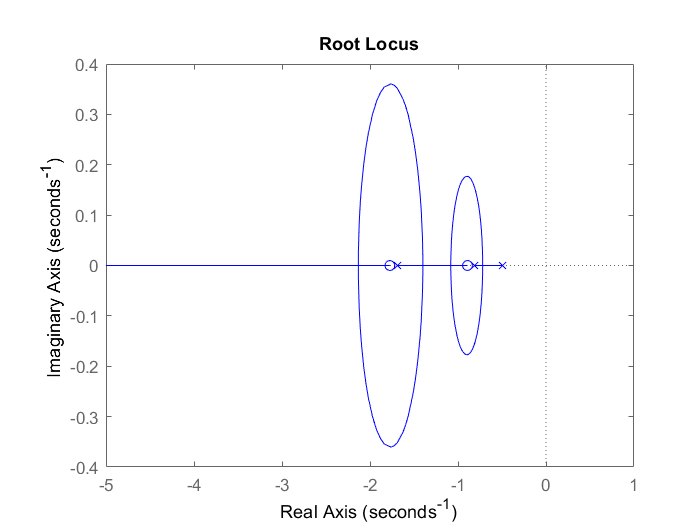

rlocus(H(1),'b')

% step(sys,100)
% grid on


The system is Stable all poles are negative

## Symbolic Solution

H

$$H = \frac{3\,s^{2}+8\,s+\frac{19}{4}}{s^{3}+3\,s^{2}+\frac{21\,s}{8}+\frac{11}{16}}$$

clear

syms t f H s

H=(3*s^2+8*s+4.75)/(s^3+3*s^2+2.625*s+0.6875)

$$H = \frac{3\,s^{2}+8\,s+\frac{19}{4}}{s^{3}+3\,s^{2}+\frac{21\,s}{8}+\frac{11}{16}}$$

f=piecewise(t<0, 0,t>=0,2)

$$f = \left\{ \begin{array}{cl} 0 & \text{ if }t<0\\ 2 & \text{ if }0\leq t \end{array}\right.$$

y=simplifyFraction((ilaplace(laplace(f)*H)),'Expand',true')

$$y = \begin{array}{l} \frac{104\,{\mathrm{e}}^{\frac{3\,t}{4}}\,\sigma_{1}}{3}-\frac{104\,\sigma_{1}\,\sigma_{3}}{3}-\frac{152\,{\mathrm{e}}^{-\frac{t}{2}}}{3}+\frac{1216\,\sigma_{1}\,\left(\sigma_{3}+\frac{3\,\sqrt{3}\,\sigma_{2}}{4}\right)}{33}-\frac{80\,\sqrt{3}\,\sigma_{1}\,\sigma_{2}}{3}+\frac{152}{11}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{5\,t}{4}}\\ \sigma_{2}=\sinh\left(\frac{\sqrt{3}\,t}{4}\right)\\ \sigma_{3}=\cosh\left(\frac{\sqrt{3}\,t}{4}\right) \end{array}$$


% simulink;
% sim("ex3.slx");
% out.ZeroStateOutput